# PRÁCTICA 1. INTRODUCCIÓN A MATLAB

## 7. Ejercicio

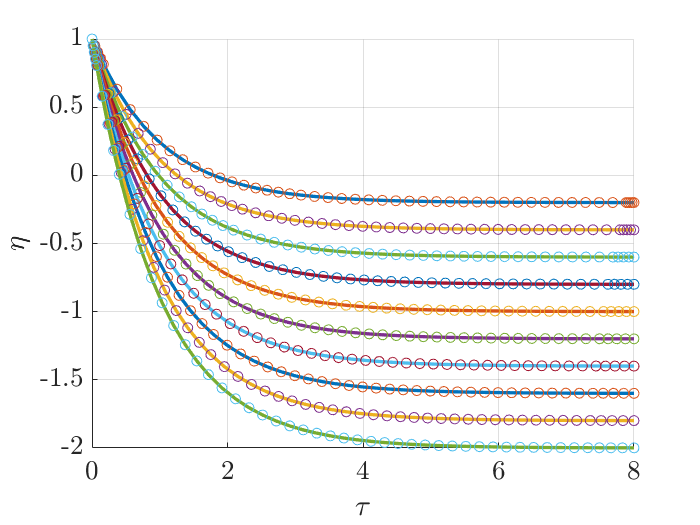

close all % Cierra todas las graficas previas
clear all % Limpia todas las variables previas
clc % Limpia la consola
for alpha=0.2:.2:2 % Abre el bucle for en alpha
% Definicion de la ecuaci´on diferencial
detadtau = @(tau,eta) -(alpha+eta);
% Tau final de la simulacion
tau_f=8;
% Valor de la condición inicial
eta0=1;
% Resolver la ecuación diferencial
[tau,eta] = ode45(@(tau,eta)detadtau(tau,eta),[0 tau_f],eta0);
% Representar graficamente
figure(1), hold on
plot(tau,eta,'LineWidth',2) % Solución numerica
plot(tau,(alpha+1)*exp(-tau)-alpha,'o') % Solución analitica
end % Cierra el bucle for en alpha
% Comandos de etiquetas y de estilo de la grafica
xlabel('$\tau$','Interpreter','LaTeX','FontSize',16)
ylabel('$\eta$','Interpreter','LaTeX','FontSize',16)
set(gca,'TickLabelInterpreter','Latex','FontSize',16)
grid on;

### 7.1 Apartado 1. (2 puntos)

Modifica el código anterior para representar el valor de $\tau$ en el momento final del vaciado $\tau_v$ dado por $\eta \left(\tau_v \right)=0$, mediante interpolación y como función de $\alpha$. Representar dicha función $\tau_v \left(\alpha \right)$numérica y compárela con la analítica obtenida de (8).

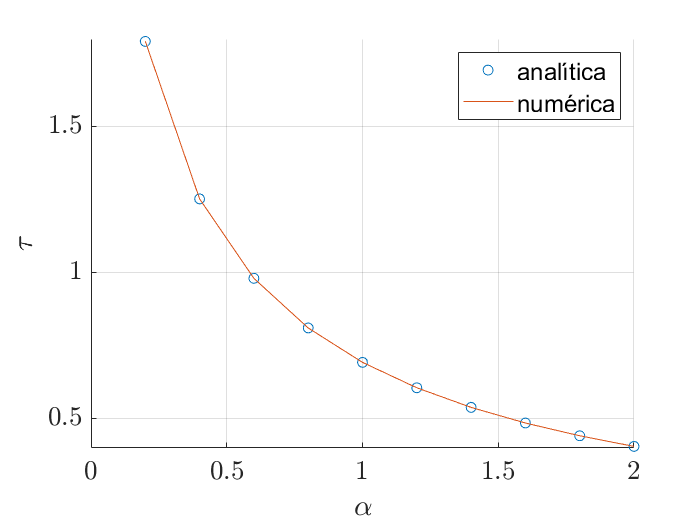

close all % Cierra todas las graficas previas
clear all % Limpia todas las variables previas
clc % Limpia la consola
i=0;
for alpha=0.2:.2:2 % Abre el bucle for en alpha
% Definicion de la ecuaci´on diferencial
detadtau = @(tau,eta) -(alpha+eta);
% Tau final de la simulacion
tau_f=8;
% Valor de la condición inicial
eta0=1;
etaf=0;
% Resolver la ecuación diferencial
[tau,eta] = ode45(@(tau,eta)detadtau(tau,eta),[0 tau_f],eta0);
% Representar graficamente
figure(2), hold on
i=i+1;
tau_v(i) = interp1(eta,tau,etaf,'spline');
alpha_v(i) = alpha;
end % Cierra el bucle for en alpha
% Comandos de etiquetas y de estilo de la grafica
xlabel('$\alpha$','Interpreter','LaTeX','FontSize',16)
ylabel('$\tau$','Interpreter','LaTeX','FontSize',16)
set(gca,'TickLabelInterpreter','Latex','FontSize',16)
grid on;
for i=1:length(alpha_v)
    tau_v_analit(i)=log((alpha_v(i)+1)/alpha_v(i));
end
hold on
plot(alpha_v,tau_v_analit,'o')
plot(alpha_v,tau_v)
legend("analítica","numérica")

### 7.2 Apartado 2. (2 Puntos)

Modifique el código anterior para obtener la viscosidad de forma numérica como función de las variables del problema. Las propiedades del dispositivo son $A=0,0314\mathrm{m2},L=0,25m,D=0,01m$ y se realiza un experimento con un fluido de densidad$\rho =950\frac{\mathrm{kg}}{m^3 }$ . Obtenga la viscosidad para un experimento en el que se utiliza una altura inicial de $h_0 =0,05m$ y se mide un tiempo de vaciado de $t_v =40s$. Para ello, utilice la función $\tau_v \left(\alpha \right)$ obtenida anteriormente.

Finalmente, compruebe que la soluci´on num´erica es correcta comparando con la soluci´on anal´ıtica. 

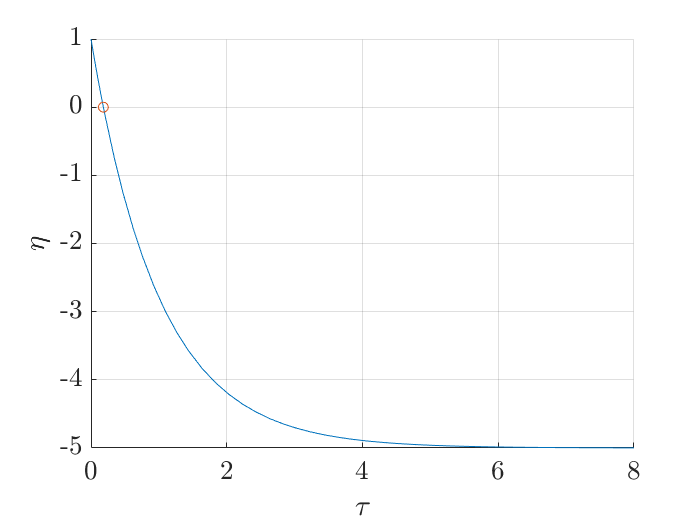

close all % Cierra todas las graficas previas
clear all % Limpia todas las variables previas
clc % Limpia la consola
% Declaración de propiedades
A=0.0314;
L=0.25;
D=0.01;
rho=950;
h0=0.05;
t_v=40;
g=9.8;
alpha=L/h0;
% Definicion de la ecuación diferencial
detadtau = @(tau,eta) -(alpha+eta);
% Tau final de la simulacion
tau_f=8;
% Valor de la condición inicial y final
eta0=1;
etaf=0;
% Resolver la ecuación diferencial
[tau,eta] = ode45(@(tau,eta)detadtau(tau,eta),[0 tau_f],eta0);
% Representar graficamente
figure(2), hold on
plot(tau,eta)
tau_v = interp1(eta,tau,etaf,'spline');
plot(tau_v,etaf,'o')
% Comandos de etiquetas y de estilo de la grafica
xlabel('$\tau$','Interpreter','LaTeX','FontSize',16)
ylabel('$\eta$','Interpreter','LaTeX','FontSize',16)
set(gca,'TickLabelInterpreter','Latex','FontSize',16)
grid on;

    tau_v_analit=log((alpha+1)/alpha);
     mu = vpa((pi*D^4*rho*g*t_v)/(128*A*L*tau_v),6)

$$mu = 0.0638616$$

mu_analit = vpa((pi*D^4*rho*g*t_v)/(128*A*L*tau_v_analit),6)

$$mu\_analit = 0.0638619$$

### 7.3. Apartado 3. (2 puntos) 

Modifique el código inicial para calcular la viscosidad integrando las ecuaciones dimensionales (4). Para ello, elimine el barrido paramétrico en α, el cual se puede considerar como medido en el experimento, y por tanto, dato de entrada. Valide el código mediante comparación con la solución analítica. 

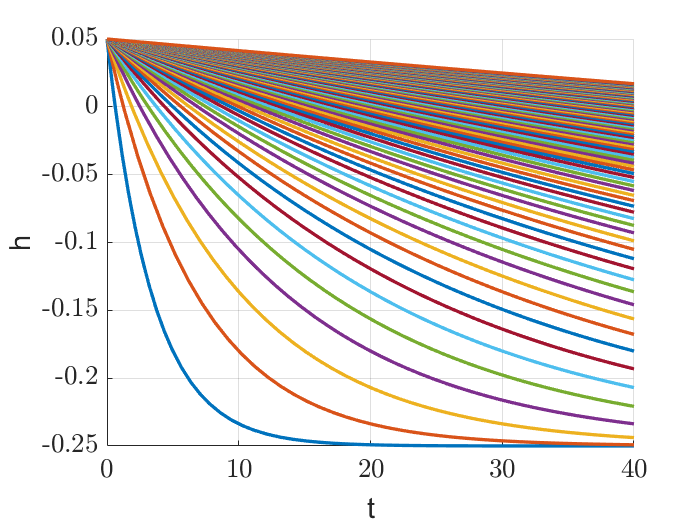

close all % Cierra todas las graficas previas
clear all % Limpia todas las variables previas
clc % Limpia la consola
% Declaración de propiedades
A=0.0314;
L=0.25;
D=0.01;
rho=950;
i=0;
g=9.8;
for mu=linspace(1e-3,1e-1,100)
i=i+1;
mu_v(i)=mu;
% Definicion de la ecuación diferencial
dhdt=@(t,h) -(pi*D^4*rho*g*(L+h))/(128*A*L*mu);
% Condiciones iniciales
h0=0.05;
t_v=40;
hf=0;
% Resolver la ecuación diferencial
[t,h] = ode45(@(t,h)dhdt(t,h),[0 t_v],h0);
t_vi(i)=interp1(h,t,hf,'spline');
% Representar graficamente
figure(1), hold on
plot(t,h,'LineWidth',2) % Solución numerica
end % Cierra el bucle for en alpha
% Comandos de etiquetas y de estilo de la grafica
xlabel('t','FontSize',16)
ylabel('h','FontSize',16)
set(gca,'TickLabelInterpreter','Latex','FontSize',16)
grid on;

mu_n=vpa(interp1(t_vi,mu_v,t_v,'spline'),6)

$$mu\_n = 0.0638619$$

mu_analit

Unrecognized function or variable 'mu_analit'.

### 7.4. Apartado 4. (4 puntos) 

Ingrese la ecuación diferencial que gobierna la velocidad de sedimentación de una esfera a bajos números de Reynolds (ecuación 14.49 de los apuntes), $\frac{4}{3}\pi R^3 \frac{\textrm{dV}}{\textrm{dt}}=\frac{4}{3}\pi R^3 \left(\rho_p -\rho \right)g-6\pi \textrm{µV}R$ . (9) con condición inicial$V\left(0\right)=V_0$ , siendo$V_0 =0\frac{m}{s}$  y $V_0 =1\frac{m}{s}$. Para ello, considere esferas de diferentes radios entre $R=1\mathrm{mm}\;y\;5\mathrm{mm}$, con valores de propiedades ρ = 1000kg/m3 , $\rho_p =7000\frac{\textrm{kg}}{m^3 }$ y µ = 1mPa·s, con gravedad g = 9,81m/s 2 . De manera opcional, se puede resolver el problema en forma adimensional, utilizando variables η = V /Vc y τ = t/tc, eligiendo convenientemente valores de la velocidad y tiempo caracter´ısticos, Vc y tc, tal que los tres t´erminos sean del mismo orden.

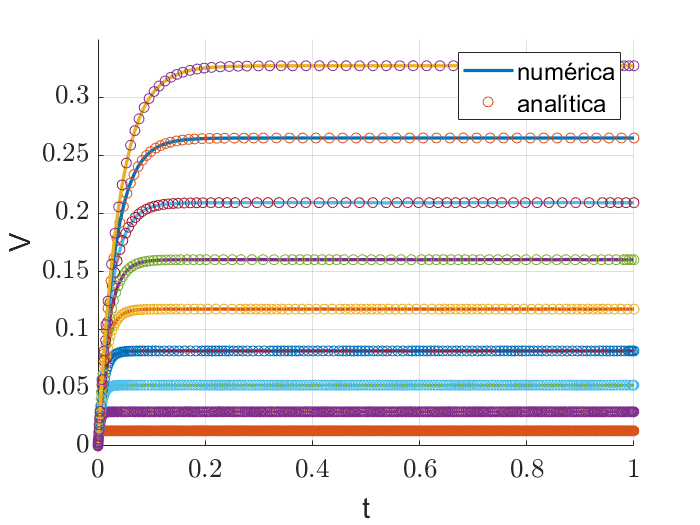

close all % Cierra todas las graficas previas
clear all % Limpia todas las variables previas
clc % Limpia la consola
rho=1000;
rho_p=7000;
mu=1;
g=9.81;
for R=0.001:.0005:0.005 % Abre el bucle for en alpha
    % Definicion de la ecuación diferencial
    dvdt = @(t,v) (4/3*pi*R^3*(rho_p-rho)*g-6*pi*mu*v*R)/(4/3*pi*R^3*rho_p);
    % tiempo final de la simulacion
    t_f=1;
    % Valor de la condición inicial
    V0=0;
    % Resolver la ecuación diferencial
    [t,v] = ode45(@(t,v)dvdt(t,v),[0 t_f],V0);
    % Representar graficamente
    figure(1), hold on
    plot(t,v,'LineWidth',2) % Solución numerica
    plot(t,((4/3*pi*R^3*g*(rho_p-rho))/(6*pi*mu*R)-(4/3*pi*R^3*g*(rho_p-rho))/(6*pi*mu*R)*exp(-6*pi*mu*R/(4/3*pi*R^3*rho_p)*t)),'o') % Solución analitica
end % Cierra el bucle for en alpha
% Comandos de etiquetas y de estilo de la grafica
xlabel('t','FontSize',16)
ylabel('V','FontSize',16)
set(gca,'TickLabelInterpreter','Latex','FontSize',16)
grid on;
legend("numérica","analítica")